# C2 - A basic codec

## C2.1 - Preliminary spectral analysis

[y, fs0] = audioread("musique.wav\musique.wav")

y =     0.0001
    0.0002
    0.0002
    0.0000
   -0.0001
   -0.0001
   -0.0001
    0.0002
    0.0002
    0.0001


fs0 = 44100

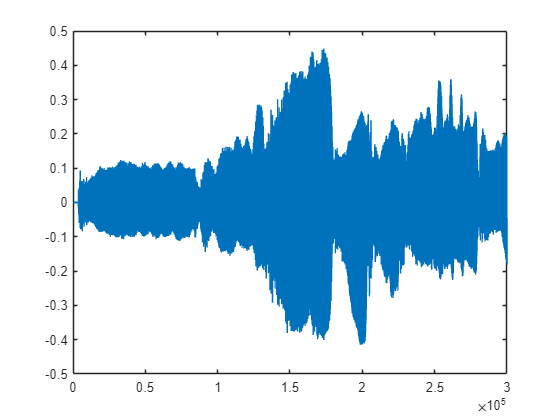

plot(y)

Some constants:

Nf = 4096;
fs = fs0;

The fourier transform:

[f, tfx] = transffourier(y, Nf, fs);

The plot:

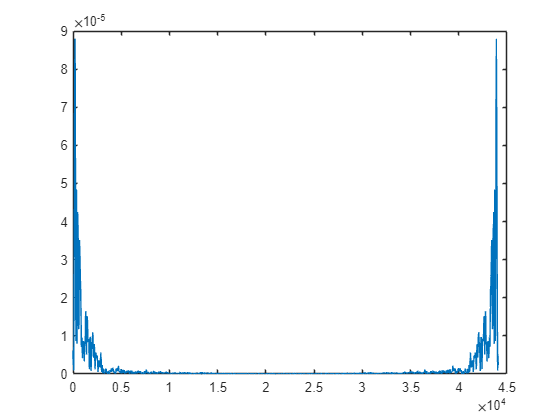

plot(f, abs(tfx))

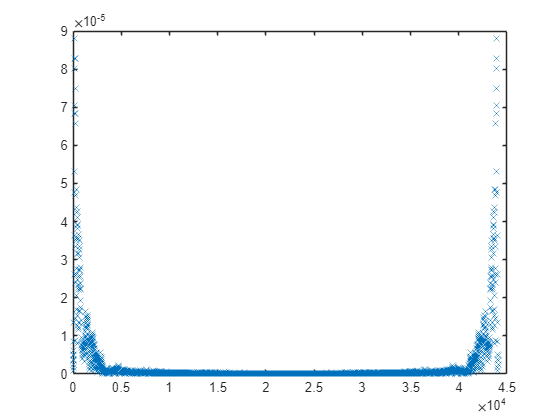

plot(f, abs(tfx), 'x')

Peaks:

[pks, locs] = findpeaks(abs(tfx), f, 'MinPeakHeight',0.95*max(abs(tfx)))

pks = 1.0e-04 *

    0.8796
    0.8796


locs = 1.0e+04 *

    0.0205    4.3895


## C2.2 Coder-decoder

[y, Fs] = audioread("musique.wav\musique.wav")

y =     0.0001
    0.0002
    0.0002
    0.0000
   -0.0001
   -0.0001
   -0.0001
    0.0002
    0.0002
    0.0001


Fs = 44100

info = audioinfo("musique.wav\musique.wav")

info = struct with fields:
             Filename: '\\data-pfe\lgorecki2026\.Bureau\sigpro\C1and2and3\musique.wav\musique.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 300000
             Duration: 6.8027
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


sound(y, Fs, info.BitsPerSample);
pause(length(y)/Fs + 0.5);

Encode

fmin = 0;
fmax = 8000;
Fs

Fs = 44100

[npt, scaling] = codeur(y, Fs, info.BitsPerSample,  fmin, fmax, "compressed\musique.wav");


Decode

[yd, fsd, bitsd] = decodeur("compressed\musique.wav", fmin, fmax, npt, scaling)

yd =    -0.0297
   -0.0038
    0.0113
    0.0122
    0.0052
   -0.0006
   -0.0008
    0.0023
    0.0042
    0.0031


fsd = 44100

bitsd = 16

Play

sound(yd, fsd, bitsd)